syms t th z(th, t)
theta = linspace(0, 2*pi, 10);

x = cos(theta);
y = sin(theta);

z(th, t) = cos(t*th)

$$z(th, t) = \cos\left(t\,\mathrm{th}\right)$$

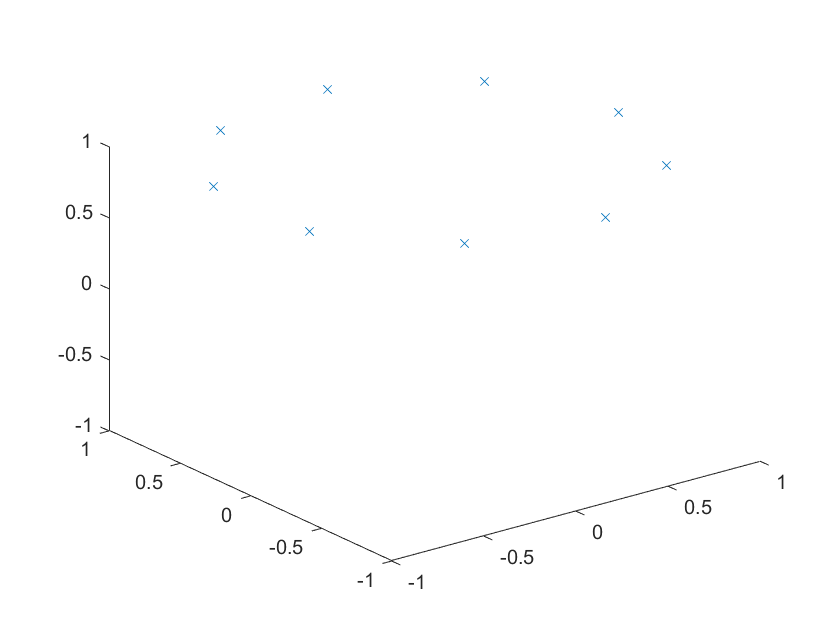

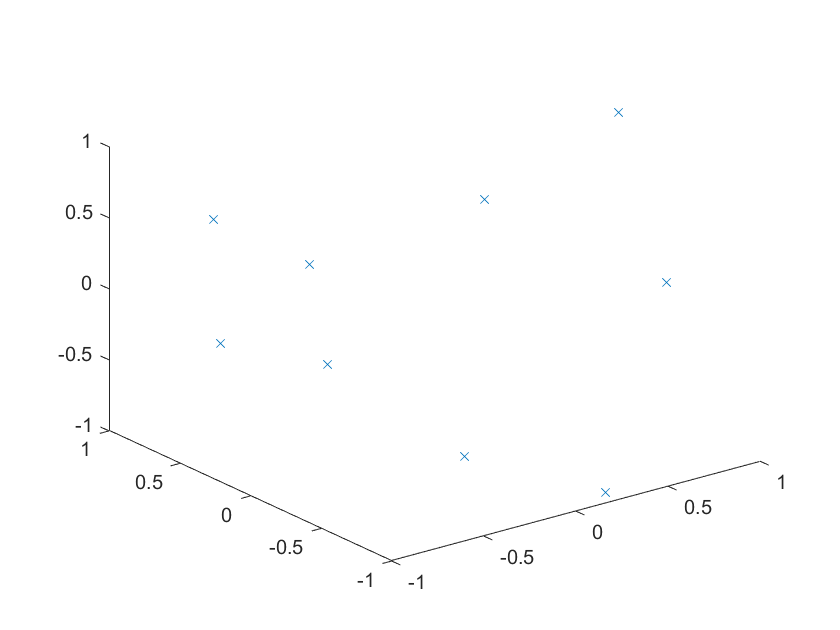



h = figure;
axis([-1,1,-1,1,-1,1])


ax = gca;
ax.NextPlot = "replaceChildren";

v = VideoWriter('newfile2.avi','Uncompressed AVI');
open(v);


loops = 40;

for i = 0:loops
    plot3(x, y, z(theta, i/20))
    writeVideo(v,getframe(h));
end


close(v);

